# Метод инвариантного погружения

### Школьная задачка


$$\sqrt{3+\sqrt{3+ \sqrt{3...}}} -?$$



$$F(n) = \sqrt {3 +_n \sqrt{3+_{n-1} ...\sqrt {3+_1\sqrt{3}}}}} $$



$$F( n \rightarrow\infty)=?$$


fval(15) % вариант процедурный 
fval_rec(0,0,15) % враиант через рекурсию

plot(arrayfun(@fval,1:15),Marker = 'diamond',linewidth=3)
title(" F(n) ")
xlabel("Число элементов")
ylabel("Значение функции")



$$F(n) = \sqrt {3 +_n \sqrt{3+_{n-1} ...\sqrt {3+_1\sqrt{3}}}} =\sqrt{3+F_{n-1}$$



$$X= \sqrt{3+X}, X^2-X-3=0 \ (X>0)$$



$$X= \frac{-1\pm\sqrt{1+12}}{2}$$


0.5*(1+sqrt(13))

Предполагаем, что решение нам известно и смотрим что будет если к нему добавить еще один элемент.

## Последовательность Фибоначчи

$X_{n+1}=X_{n} + X_{n-1}$ , $X_1=1,X_2=1$

### Процедурное решение и рекурсия

Процедурное решение - суммирование в цикле.

Функциональное решение - суммирование при помощи рекурсии

fib_dir(7)
fib_rec(7)

tic;fib_dir(35);toc
tic;fib_rec(35);toc

Почему рекурсия медленно работает можно понять если посмотреть граф вызова

plotFibTreeGraph(5)

### Memoization pattern

Как видно из графа для последовательности фибоначчи, при рекурсии происходит частое повторение одного и того же паттерна (так как следующий элемент выражается через предыдущие). Соотвественно, идея состоит в том, чтобы хранить отдельно уже посчитанные элементы последовательности, чтобы не надо было их пересчитывать

#### Класс dictionary

Словарь  - это коллекция данных, организованная по принципу ключ-элемент, данные доступны по ключу, разные элементы не могут иметь один ключ. Словари адаптированы под возможность раширения множества.

d = dictionary("a",10)
f = @(d,x,y)insert(d,x,y)

% словарь, как и остальные базовые коллекции (struct,cell и др.) 
% используют pass-by-value
f(d,"b",34)
d

Обертка ("wrapper") для стандартного словаря в матлаб, чтобы нам удобнее было писать данные 

Рекурсивная функция с запоминанием значений

fib_mem(30)

clear fib_mem

NMAX=100
t_fib_dir= zeros([NMAX,1]);t_fib_rec = t_fib_dir;t_fib_mem_rec=t_fib_rec;
for n = 1:NMAX
     %tic;fib_rec(n);t_fib_rec(n) = toc;
     tic;fib_mem(n);t_fib_mem_rec(n) = toc;
     tic;fib_dir(n);t_fib_dir(n) = toc;
end
plot(1:NMAX,t_fib_rec,1:NMAX,t_fib_mem_rec,1:NMAX,t_fib_dir)
yscale log
legend(["Рекурсия"  "Рекурсия с памятью" "Прямое суммирование"])
xlabel("Число элементов последовательности")
ylabel("Время выполнения, с")

### Уравнение переноса излучения в двухпотоковом приближении

Будем решать следующую задачу:

Пусть у нас есть некоторая одномерная среда длиной $X$, в которой распространяется излучение (поток частиц). Вероятность того, что частица  на участке пути длиной $\Delta$ равна $\sigma \cdot \Delta$. Доля частиц, рассеиваемых вперед (продолжающих двигаться в томже направлении, что и до рассеяния ) равна $f$, а в противоположном  - $b$ ($f + b = 1$). Все параметры ($\sigma,f,b$) могут зависеть от координат. Излучение падает с левого края.  

#### Классический подход

Будем рассматривать задачу в двух потоковом приближении, то есть у нас есть плотность излучения движущегося вправо ($U$) и влево  - $V$. 

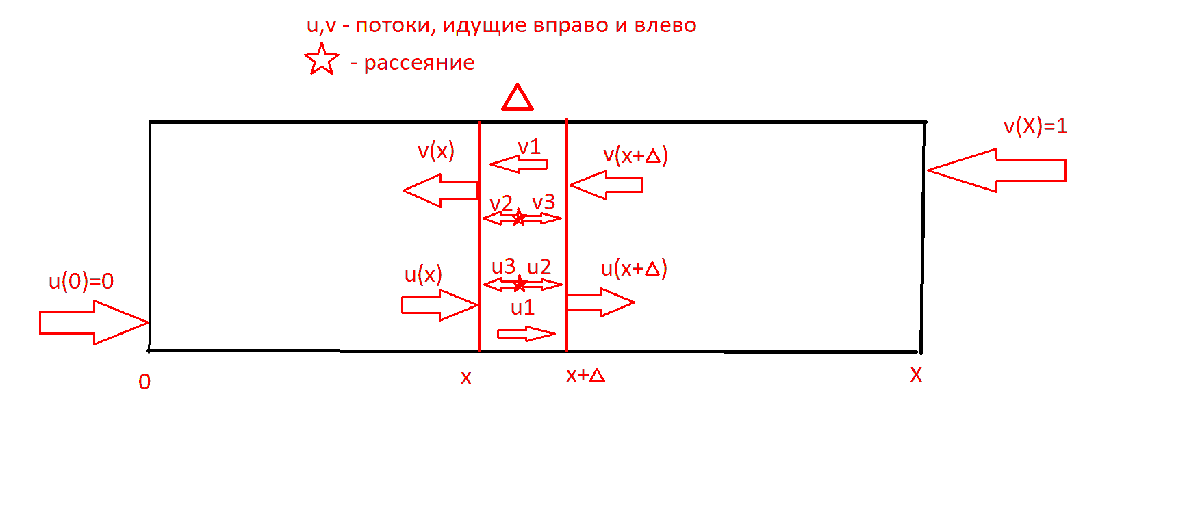

Рассмотрим небольшой участок пути излучения длиной $\Delta$ и, чтобы сформулировать дифференциальное уравнение переноса, рассмотрим потоки излучения на этом участке. Поток излучения в объеме этого элемента формулируется как сумма потоков движущихся  влево и вправо:

Для излучения, движущегося вправо:


$$U(x+\Delta)=U_1 + U_2 + U_3$$


$U_1 = (1-\sigma\Delta)U(x)$ - излучение, которое пролетает через слой не рассеиваясь ($1 - \sigma\Delta$) - вероятность того, что рассеяния не произойдет (единица минус вероятность рассеяния $\sigma\Delta$).

$U_2 =f \sigma\Delta U(x)$  - доля излучения, рассеянного вперед

$U_3 =b \sigma\Delta V(x+\Delta)$ - часть потока, идущего влево, рассеянная назад (для потока, идущего вправо - это попутное направление).


$$U(x+\Delta) - U(x)=\sigma\Delta[(f-1)U(x) + b V(x+\Delta)] + o(\Delta)$$


Аналогично для потока вправо: $V(x) = (1-\sigma \Delta)V(x+\Delta) +f \sigma\Delta V(x+\Delta) + b\sigma\Delta U(x)$


$$V(x+\Delta) - V(x)=\sigma\Delta[- b U(x) - (f-1)V(x+\Delta)] + o(\Delta)$$


Теперь можно поделить на $\Delta$ и устремить его к нулю, что даст систему дифференциальных уравнений:


$$\begin{cases} \matrix{\frac{dU}{dx} = \sigma [(f-1)U(x) + b V(x)] \cr \frac{dV}{dx} = \sigma[ -b U(x) - (f-1)V(x)]  } \end{cases} $$


Удобно систему переписать в виде одного векторного уравнения: 

$\frac{d}{dx} \vec{Y} = \sigma[ \matrix{ f-1 & b \cr -b & -(f-1)} ]\vec{Y}; \ \ \vec{Y}=  \matrix{U \cr V}$                                        (1)


$$\frac{d}{dx} \vec{Y} = T\vec{Y}$$


Граничные условия :

$U(0)=0$  - слева излучение не падает

$V(X)=1$- справа излучение падает

Это краевая задача 


$$\frac{d}{dx}\vec{Y}=f(x,\vec{Y})$$


$G(\vec{Y}(0),\vec{Y}(X))=\Gamma\cdot[\vec{Y}(0);\vec{Y}(X)] = \vec{0}$ - граничные условия ($x=0, x=X$  - гранцы области) 

В нашем случае :

$f(x,\vec{Y}) = T(x)\vec{Y}$ (если $\sigma,f,b$ не зависят от координат, то $T$ - постоянная матрица) 

Граничные условия:


$$[\matrix{1 & 0\cr 0 & 1}]\cdot [\matrix{U(0) & U(X)\cr V(0) & V(X)-1 }]=[\matrix{0\cr 0}]$$


Матлаб имеет несколько численных методов для решения краевых задач.

Так как правая часть у нас имеет некоторые параметры, сделаем функцию, которая оборачивает конкретные знаечния параметров и возвращает анонимную функцию в нужной форме, правая часть нашего дифференциального уравнения:

Граничные условия в форме:

Также для решения кравевых задач требуется стартовая аппроксимация, мы возьмем линейную зависимость:

### Метод инвариантного погружения

В действительности нам, как правило, не нужны внутренние поля, нас интересуют коэффициенты отражения и пропускания на границе. 

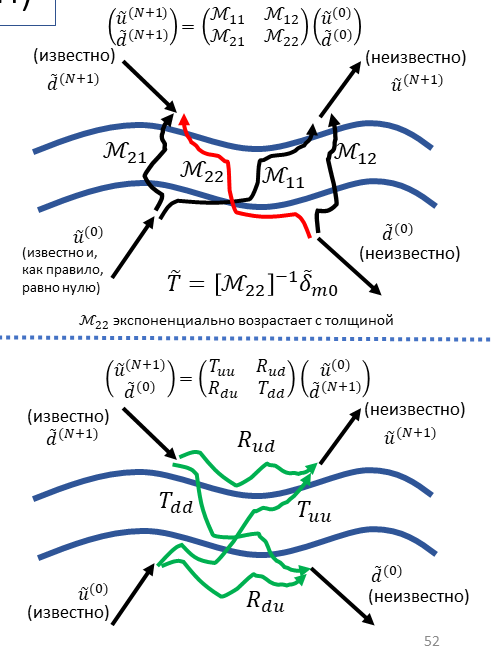

Поэтому будем писать уравнения сразу для отражения (для пропускания не будем, но логика там такая же).

 Представим, что, во-первых, 

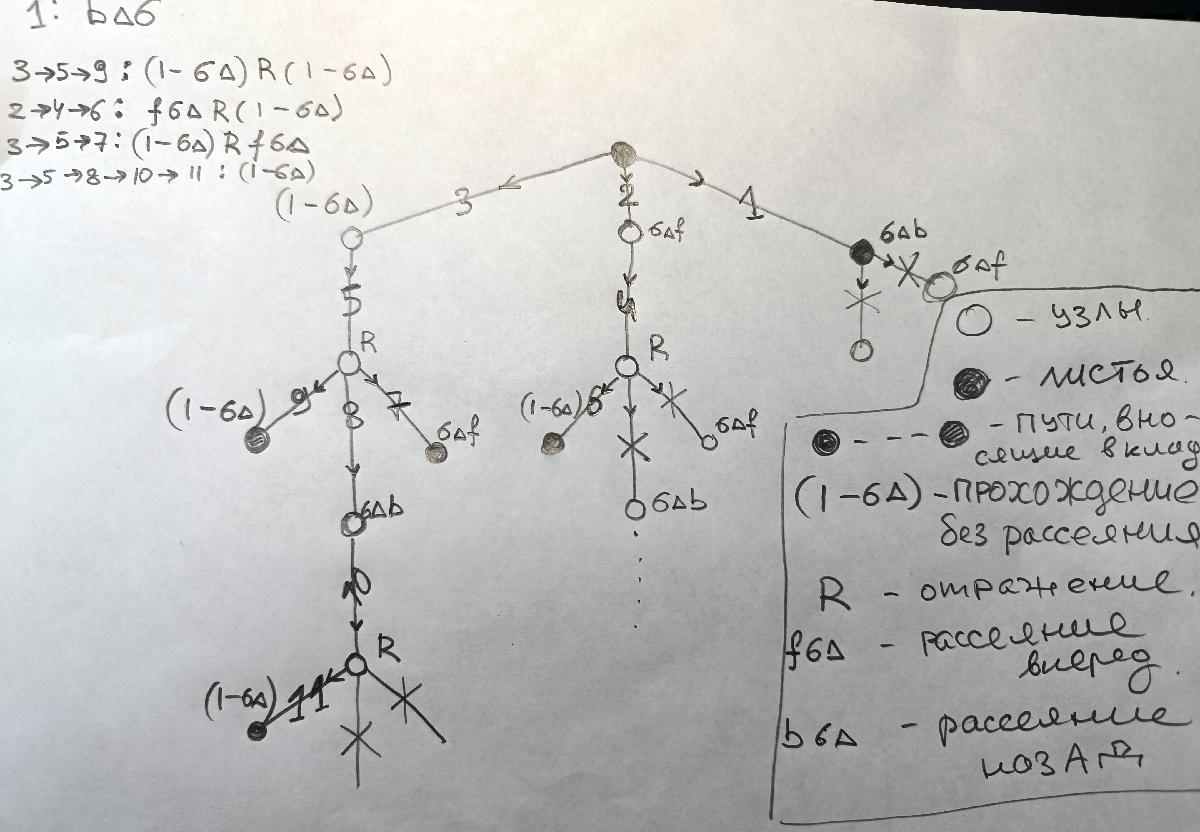

ns = "1-\sigma\delta";fs = "f\sigma\delta";
bs = "b\sigma\delta";rl = "R";o = " #1"

o = " #1"

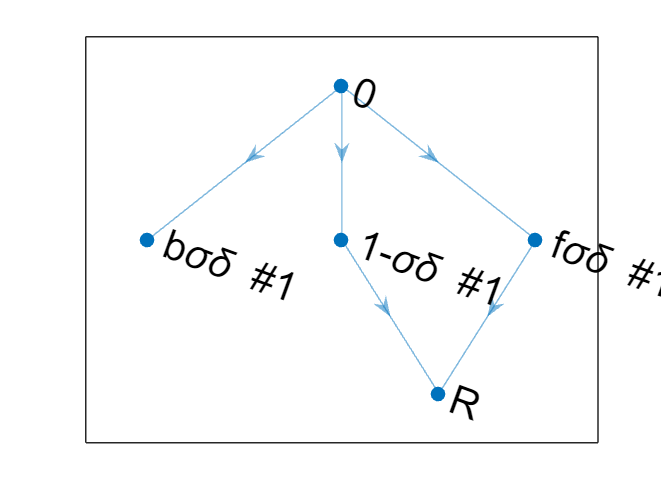

plot(digraph(["0","0","0",ns+o,fs+o], ...
    [ns+o,fs+o,bs+o,rl,rl]),NodeFontSize=14)

xmesh = linspace(0,1,30);% строим сетку, на которой будет
% искаться решение краевой задачи
solinit = bvpinit(xmesh, @guess) % исходное распределение

solinit = struct with fields:
    solver: 'bvpinit'
         x: [0 0.0345 0.0690 0.1034 0.1379 0.1724 0.2069 0.2414 0.2759 0.3103 0.3448 0.3793 0.4138 0.4483 0.4828 0.5172 0.5517 0.5862 0.6207 0.6552 0.6897 0.7241 0.7586 0.7931 0.8276 0.8621 0.8966 0.9310 0.9655 1]
         y: [2×30 double]
     yinit: @guess


sigma=5.484

sigma = 5.4840

% коэффициент f
forward_fraction = 0.529

forward_fraction = 0.5290

alfa = 0

alfa = 0

% коэффициент b в уравнении
backward_fraction = 1 - forward_fraction

backward_fraction = 0.4710

dy_fun = dy(sigma,alfa,backward_fraction,forward_fraction)

dy_fun = function_handle with value:
    @(x,y)T*y(:)


sol = bvp4c(dy_fun, @bcfun, solinit)

sol = struct with fields:
    solver: 'bvp4c'
         x: [0 0.0345 0.0690 0.1034 0.1379 0.1724 0.2069 0.2414 0.2759 0.3103 0.3448 0.3793 0.4138 0.4483 0.4828 0.5172 0.5517 0.5862 0.6207 0.6552 0.6897 0.7241 0.7586 0.7931 0.8276 0.8621 0.8966 0.9310 0.9655 1]
         y: [2×30 double]
        yp: [2×30 double]
     stats: [1×1 struct]


t = sol.y(2,1);
r = sol.y(1,end);
a = 1 - t - r

a = 1.1102e-16

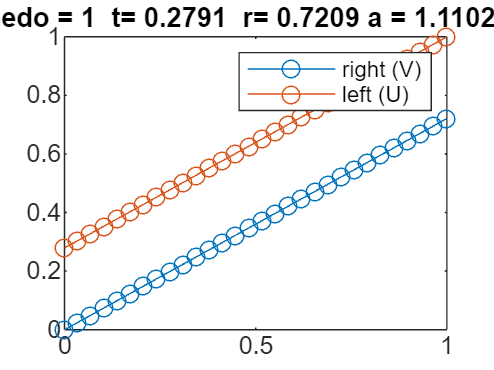


plot(sol.x, sol.y,"-o" )
legend(["right (V)", "left (U)"])
title ( "albedo = "+ ...
    string(sigma/(sigma+alfa)) ...
    +"  t= "+string(t)+ ...
    "  r= "+string(r) + ...
    " a = "+string(a))

Когда потоки в объеме расчетной области найдены, коэффициент отражения это $R =U(X)= \vec{Y}(X)(1)$ - последний элемент  в функции для потока, движущегося вправо.

А коэффициент пропускания:

 $T =V(0)= \vec{Y}(0)(2)$ - то есть второй элемент вектора решения на левой границе (поток, идущий с границы влево)


dR_fun = dRdx(sigma,alfa,backward_fraction,forward_fraction)

dR_fun = function_handle with value:
    @(x,R)sigma*(b+2*((f-1))*R+R.*R*b)-2*alfa*R


F = ode;
F.ODEFcn = dR_fun;
F.InitialValue = 0;
sol_inv = solve(F,0,1)

sol_inv =   ODEResults with properties:

        Time: [0 1.9450e-05 3.8899e-05 5.8349e-05 7.7799e-05 1.7505e-04 2.7230e-04 3.6954e-04 4.6679e-04 9.5303e-04 0.0014 0.0019 0.0024 0.0048 0.0073 0.0097 0.0121 0.0243 0.0364 0.0486 0.0608 0.0858 0.1108 0.1358 0.1608 0.1858 0.2108 … ] (1×61 double)
    Solution: [0 5.0235e-05 1.0047e-04 1.5069e-04 2.0091e-04 4.5194e-04 7.0283e-04 9.5361e-04 0.0012 0.0025 0.0037 0.0049 0.0062 0.0124 0.0184 0.0245 0.0304 0.0590 0.0860 0.1115 0.1357 0.1814 0.2225 0.2596 0.2934 0.3242 0.3525 0.3785 … ] (1×61 double)


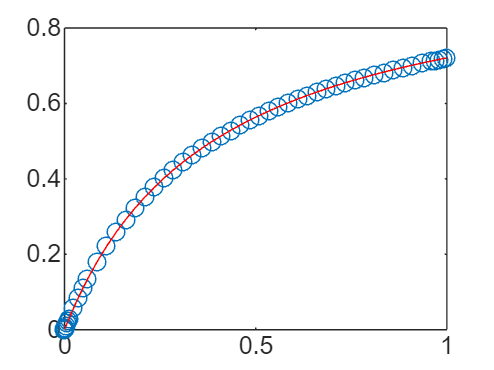


r_dir =  zeros(size(sol_inv.Time));
t_dir =  ones(size(sol_inv.Time));
for i =2:numel(sol_inv.Time)
    [r_dir(i),t_dir(i)] = r_direct(sol_inv.Time(i),alfa,sigma,forward_fraction,backward_fraction);
end
plot(sol_inv.Time,r_dir,'o',sol_inv.Time,sol_inv.Solution,'r')

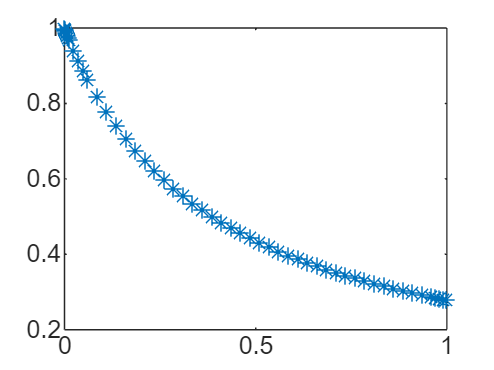

plot(sol_inv.Time,t_dir,'*')

%% задачка
function s = fval(N)
% прямое суммирование 
    a = 3;
    s = sqrt(3);
    for i = 1:N
        s = sqrt(s + a);
    end
end
function s = fval_rec(s,i,N)
% суммирование через рекурсию
    a=3; 
    if i>=N
        return
    else
         s= sqrt(a + fval_rec(s,i+1,N));
    end
end
%% последовательность фибоначчи
function val = fib_dir(N)
% процедурное решение
    if N<=2
        val = 1;
        return
    end
    val = 0;
    x1 = 1;
    x2 = 1;
    for i = 3:N
        val = x1 + x2;
        x1 = x2;
        x2 = val;
    end
end
function val = fib_rec(N)
% рекурсивное решение
    if N<=2
        val = 1;
        return
    end
    val  = fib_rec(N-1) + fib_rec(N-2);
end
function plotFibTreeGraph(n)
    % для построения графа используем рекурсию в процедурном 
    % стиле
    edges = [];
    labels = string([]);
    nodeCount = 0;
    
    % рекурсиный вызов (как в простой версии 
    % рекурсивной функции, только каждый нод добавляется в граф)
    % nested function (переменные edges,labels и nodeCount) для нее
    % глобальные
    function nodeID = buildFibGraph(num)
        nodeCount = nodeCount + 1; 
        nodeID = nodeCount;
        val = fib_mem(num);
        labels(nodeID) = "#"+string(num)+"="+string(val);
        if num <= 2
            return; 
        end
        % рекурсиный вызов
        leftID = buildFibGraph(num - 1);
        rightID = buildFibGraph(num - 2);
        
        edges(end+1, :) = [nodeID, leftID];
        edges(end+1, :) = [nodeID, rightID];
    end

    % запуск расчета
    buildFibGraph(n);
    
    % строим направленный граф 
    G = digraph(edges(:,1), edges(:,2));
    
    % рисуем граф
    figure;
    h = plot(G, 'Layout', 'layered', 'NodeLabel', labels, 'Direction','down', ...
        'Interpreter','none', 'NodeFontSize', 10, 'MarkerSize', 7);
    title(sprintf('Фибоначчи n = %d', n));
    set(gca,'XTick',[], 'YTick', []);
end
%% Решение уравнения переноса в двух-потоковом приближении

function fun = dy(sigma,alfa,b,f)
 % функция оборачивает конкретные значения параметров в анонимную функцию, 
 % которая будет использована в решателе краевых задач 
    T = zeros(2);
    T(1,1) = sigma*(f-1)-alfa;
    T(1,2) = sigma*b;
    T(2,1) = -T(1,2);
    T(2,2) = -sigma*(f-1)-alfa;
    fun = @(x,y)T*y(:);% первый аргумент  - независимая переменная 
    % второй аргумент - само значение функции
end
function res = bcfun(y0,yX)
% граничные условия для решения краевой задачи 
% для классической постановки
res = [y0(1)
       yX(2)-1];
end
function g = guess(x)
% стартовая аппроксимация
    g = [0.5*x 
        x];
end

function [r,t] = r_direct(X,alfa,sigma,f,b)
        dy_fun = dy(sigma,alfa,b,f);
        xmesh = linspace(0,X,10);
        solinit = bvpinit(xmesh, @guess);
        sol = bvp4c(dy_fun, @bcfun, solinit);
        t = sol.y(2,1);
        r = sol.y(1,end);    
end
function fun =dRdx(sigma,alfa,b,f)
    fun = @(x,R) sigma*(b + 2*((f-1))*R  + R.*R*b) - 2*alfa*R;
end
function plot_invar_graph()
ns = "1-\sigma\Delta";fs = "f\sigma\Delta";
bs = "b\sigma\Delta";rl = "R";

edges = ["0","0","0";
    "3:"+ns,"2:"+fs,"1:"+bs];
edges = [edges,...
            ["3:"+ns,"2:"+fs;
             "5:"+rl,"4:"+rl]];
edges = [edges,...
            ["5:"+rl,"5:"+rl,"5:"+rl;
            "9:"+ns,"8:"+bs,"7:"+fs]];
edges = [edges,...
            ["4:"+rl,"4:"+rl,"4:"+rl;
            "6:"+ns,bs+"2end",fs+"2end"]];
dead_nodes = [bs+"2end",fs+"2end",bs+"3end",fs+"3end"];
% собираем граф
G = digraph(edges(1,:),edges(2,:));
p = plot(G,NodeFontSize=16,MarkerSize=10);
% делаем маркеры для листьев
all_leaf = find(outdegree(G) == 0);
deadLeaf_inds  = [];
leafNodes_inds = [];
for n = transpose(all_leaf)
    cnd = G.Nodes{n,1}{1};
    if contains(cnd,dead_nodes)
        deadLeaf_inds(end+1)= n;
    else
        leafNodes_inds(end+1)=n;
    end
"S"
end
dead_leafNodes = G.Nodes(deadLeaf_inds,1);
real_leafNodes = G.Nodes(leafNodes_inds,1);

highlight(p, table2cell(leafNodes), 'NodeColor','g')

end
